# Initializer.mlx

#### This file specifies the simulation parameters, stores the outputs from the PSSE simulation and plots them.

pathName = ["C:\Users\aryan\Documents\" + ... 
    "documents_general\psse_files\" + ...
"python_practice_psse\e0040\outputs\dablab_repo\"];
addpath(pathName)
latex_interpreter

#### Specify simulation parameters: system name, sampling rate, window size, etc. in order to store it in a table for reference.

tic
system_name = 'ieee9'

system_name = 'ieee9'

run_number = 1

run_number = 1

#### sampling_rate is actually the time between consecutive samples (kind of misleading variable name).

sampling_rate = 0.01;
downsampling_ratio = 1

downsampling_ratio = 1

#### similarly downsampled_rate is actually the time between consecutive samples after downsampling.

downsampled_rate = sampling_rate*downsampling_ratio;
T = 10%Window size in seconds

T = 10

W = T/downsampled_rate

W = 1000

window_moving_ratio = 1/20 %how far ...

window_moving_ratio = 0.0500

% will window move (wrt window length) for each subsequent detrended analysis
bifurcation_limit  = 0.90

bifurcation_limit = 0.9000

folder_name = 'saved_outputs/'; %subfolder where data will be stored
convolutionMarginRatio = 0.00

convolutionMarginRatio = 0

####  Fish out desired output parameters from the PSSE outfile.

xlsxname = strcat(system_name,'_outfile', string(run_number), '.xlsx')

xlsxname = "ieee9_outfile1.xlsx"

opts = detectImportOptions(xlsxname, 'NumHeaderLines', 3);
opts.VariableNamingRule = 'modify';
xlsxtable = readtable(xlsxname, opts);


string0 = 'Time';
string1 = 'POWR';
string2 = 'BUS';
string3 = 'PLOD';
string4 = 'FREQ';
string5 = 'VOLT';
string6 = 'CKT';
string7 = 'MVA';

varNames = xlsxtable.Properties.VariableNames;
times = xlsxtable(:, contains(varNames,string0));
times.Properties.VariableNames = {'time'};

#### Segregating the 'normal' run from the 'disturbed' (with a steady load demand increment) run.

rows = times.time > 1.0;
times = times.time(times.time > 1.0);

% colors = [ [18,14,249]
%     [67,127,29] 
%     [230,43,52]
%    [7,7,7]]/255;


pgens = xlsxtable(rows, contains(varNames, string1) ...
    & contains(varNames, string2));
pgensArr = table2array(pgens);
save(strcat(folder_name,'pgens_',system_name,'.mat'), 'pgensArr');

ploads = xlsxtable(rows, contains(varNames, string3));
ploadsArr = table2array(ploads);
save(strcat(folder_name,'ploads_',system_name,'.mat'), 'ploadsArr');

freqs = xlsxtable(rows,contains(varNames,string4));
freqsArr = table2array(freqs);
save(strcat(folder_name,'freqs_',system_name,'.mat'), 'freqsArr');

volts = xlsxtable(rows, contains(varNames, string5));
voltsRawArr = table2array(volts);
save(strcat(folder_name,'voltsRaw_',system_name,'.mat'), 'voltsRawArr');


numBuses = size(volts, 2)

numBuses = 9

volts = volts{:,:};
[voltageSamplingStartsFrom, startIdx] = max(volts);
bifurcationIdx = find(volts < bifurcation_limit,...
    1, 'first')

bifurcationIdx = 8438

% convolutionMarginRatio = 0.00 %Percentage ...
% of truncated (pre-bifurcation) values to be *further* ...
% truncated to accommodate for smoothing peak artifact.
lastIdx = size(volts, 1)

lastIdx = 10724

#### Briefly deviating to fill in some of the newly acquired values (bifurcationIdx, lastIdx) into the NominalValues table.

variableList = {'system_name', 'run_number', ...
    'sampling_rate', 'downsampling_ratio','T','W', ...
    'window_moving_ratio', ...
    'bifurcation_limit','bifurcationIdx','lastIdx', 'convolutionMarginRatio'};
firstRow = {system_name, run_number, sampling_rate, downsampling_ratio, T, W, ...
    window_moving_ratio, ...
    bifurcation_limit, bifurcationIdx, lastIdx, convolutionMarginRatio};
nominalValuesTable = array2table(firstRow, 'VariableNames',variableList);
tableName = strcat(folder_name, 'nominalValuesTable_', system_name, '_', ...
    string(run_number), '.csv')

tableName = "saved_outputs/nominalValuesTable_ieee9_1.csv"

writetable(nominalValuesTable, tableName);

voltsTruncatedArr = volts(1:bifurcationIdx, :);
voltsTruncatedArrName = strcat(folder_name,'voltsTruncated_', ...
    system_name, '_', string(run_number), '.mat');
save(voltsTruncatedArrName, 'voltsTruncatedArr');

mvaflows = xlsxtable(rows, contains(varNames, string6) ...
    & contains(varNames, string7));
mvaflowNames = mvaflows.Properties.VariableNames;
indicesToDelete = [];
for i = 1:length(mvaflowNames)
    if mvaflowNames{i}(4) > mvaflowNames{i}(7)
        indicesToDelete = [indicesToDelete i];
    end
end
mvaflowNames(indicesToDelete) = [];
mvaflowsArr = mvaflows{:,mvaflowNames};
save(strcat(folder_name,'mvaflows_', ...
    system_name, '_', string(run_number), '.mat'), 'mvaflowsArr');


#### Calculate Branch Current Flows.

busesInEachBranch = [1 2 3 4 4 5 6 7 8];
currentsArr = 1/sqrt(3)*mvaflowsArr./volts(:, busesInEachBranch);
save(strcat(folder_name,'currents_', system_name, '_',...
    string(run_number), '.mat'), 'currentsArr');

indicesToPlot1 = 1:downsampling_ratio:bifurcationIdx;
xaxis1 = (bifurcationIdx - indicesToPlot1)*sampling_rate/(60);

#### Plot Bus Frequencies.

figure('Name', 'Bus Frequencies')
plot(xaxis1, freqs{indicesToPlot1,1:end});
xlabel1 = xlabel('Time to bifurcation (minutes)');
set(gca,'xdir','reverse')
title1 = title('Bus Frequencies');
ylabel1 = ylabel('$\Delta f$ in pu at 60Hz base.');
if strcmp(system_name,'ieee9')
    legend('$\Delta f_1$', '$\Delta f_2$', '$\Delta f_3$', ...
    '$\Delta f_4$', '$\Delta f_5$', '$\Delta f_6$', ...
    '$\Delta f_7$', '$\Delta f_8$', '$\Delta f_9$');
elseif strcmp(system_name,'ieee39')
    legend('$P_{Gen} 30$', '$P_{Gen} 31$', 'and so on');
else
    legend;
end

#### Preprocess for saving plots

pdf_location_name = 'pdf/';
if T < 1
    windowInSec = strcat('point', string(10*T),'_sec');
else
    windowInSec = strcat(string(T),'_sec');
end
imagePdfName = strcat(pdf_location_name, system_name, '_', string(run_number),...
    '_busFrequencies_T_', windowInSec)

imagePdfName = "pdf/ieee9_1_busFrequencies_T_10_sec"

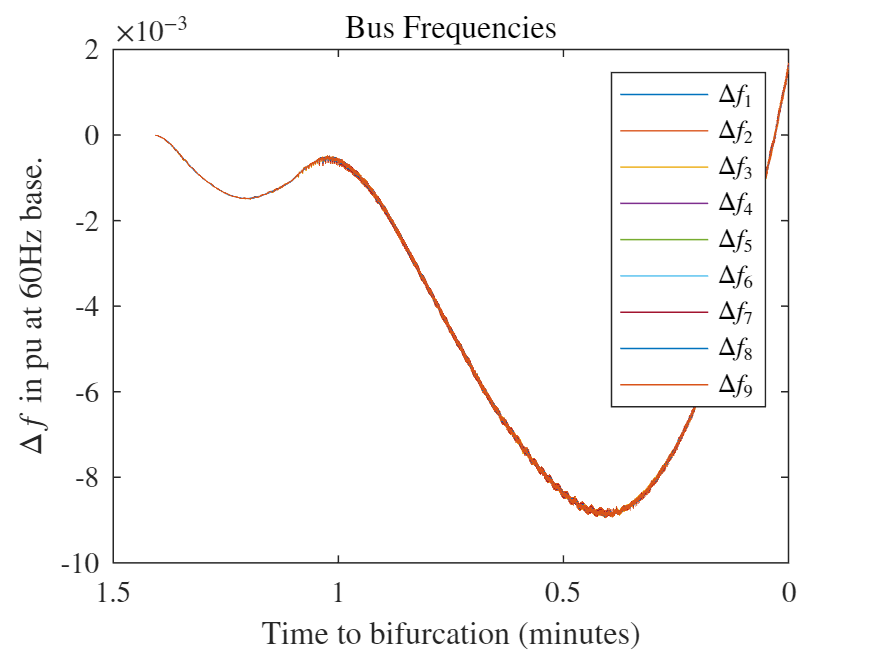


set(gcf, 'PaperSize', [24 12]); %set the paper size to what you want  
print(imagePdfName,'-dpdf', '-fillpage') % then print it

#### Plot Generation Values.

figure('Name', 'Generation Values')
plot(xaxis1, pgens{indicesToPlot1,  1:end});
set(gca,'xdir','reverse')
xlabel('Time to bifurcation (minutes)');
title('Real Power Generations');
ylabel('$P_{Gen}$ in pu on a 100MW base.');
if strcmp(system_name,'ieee9')
    legend('$P_{Gen} 1$', '$P_{Gen} 2$', '$P_{Gen} 3$');
elseif strcmp(system_name,'ieee39')
    legend('$P_{Gen} 30$', '$P_{Gen} 31$', 'and so on');
else
    legend;
end

imagePdfName = strcat(pdf_location_name, system_name, '_', string(run_number),...
    '_realPowerGenerations_T_',windowInSec)

imagePdfName = "pdf/ieee9_1_realPowerGenerations_T_10_sec"

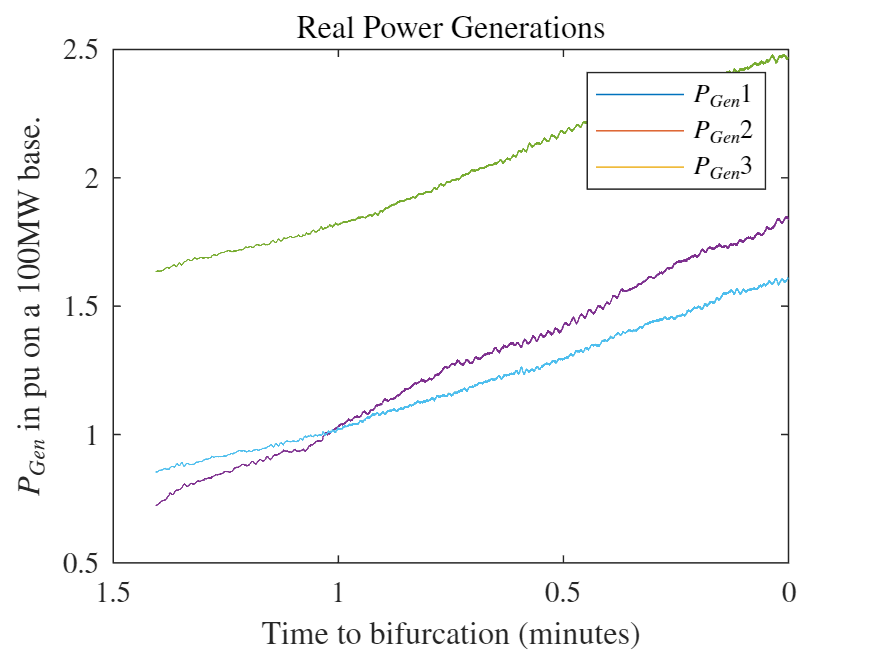

set(gcf, 'PaperSize', [24 12]); %set the paper size to what you want  
print(imagePdfName,'-dpdf', '-fillpage') % then print it

#### Plot Load Demand Values.

figure('Name', 'Load Values')
plot(xaxis1, ploads{indicesToPlot1,1:end});
set(gca,'xdir','reverse')
xlabel('Time to bifurcation (minutes)');
title('Real Power Loads')
ylabel('$P_{Load}$ in pu on a 100MW base.');
if strcmp(system_name,'ieee9')
    legend('$P_{Load} 5$', '$P_{Load} 6$', '$P_{Load} 8$');
elseif strcmp(system_name,'ieee39')
    legend('$P_{Load} 1$', '$P_{Load} 231$', 'and so on');
else
    legend;
end

imagePdfName = strcat(pdf_location_name, system_name, '_', string(run_number),...
    '_realPowerLoads_T_',windowInSec)

imagePdfName = "pdf/ieee9_1_realPowerLoads_T_10_sec"

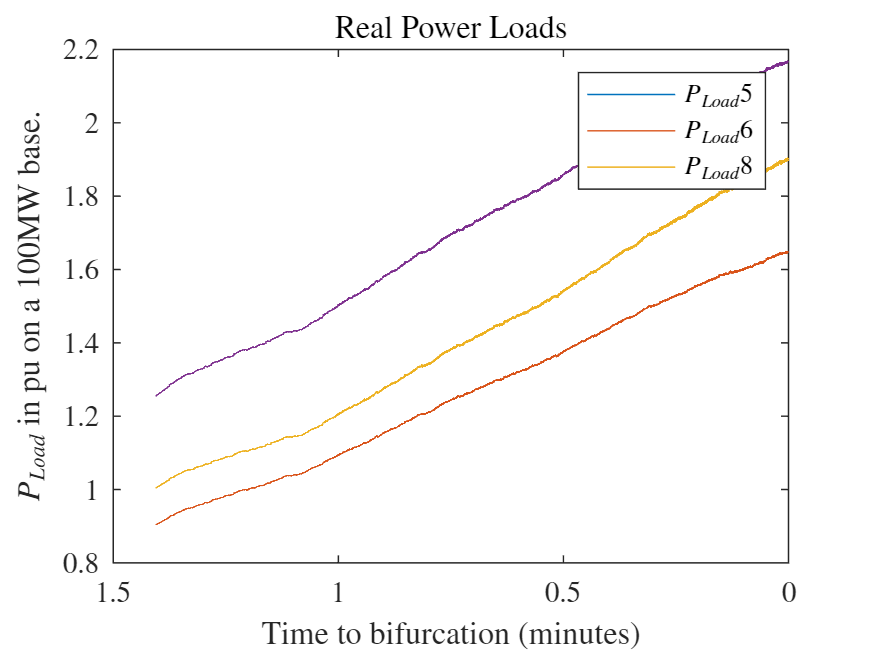

set(gcf, 'PaperSize', [24 12]); %set the paper size to what you want  
print(imagePdfName,'-dpdf', '-fillpage') % then print it

#### Plot Branch MVA flows.

figure('Name', 'Branch MVA flows')
plot(xaxis1, ...
    mvaflowsArr(indicesToPlot1,1:end));
set(gca,'xdir','reverse')
title('Branch MVA Flow Magnitudes');
xlabel('Time to bifurcation (minutes)');
ylabel('$P_{flow}$ in MW.');

labelMVAflows = {'$1 to 4$', '$2 to 7$', '$3 to 9$', ...
    '$4 to 5$', '$4 to 6$', '$5 to 7$', ...
    '$6 to 9$', '$7 to 8$', '$8 to 9$'};
name_labelMVAflows = strcat(folder_name, 'labelMVAflows_'...
    , system_name, '.mat');
save(name_labelMVAflows, "labelMVAflows");

imagePdfName = strcat(pdf_location_name, system_name, '_', string(run_number), ...
    '_branchMVAs_T_',windowInSec)

imagePdfName = "pdf/ieee9_1_branchMVAs_T_10_sec"

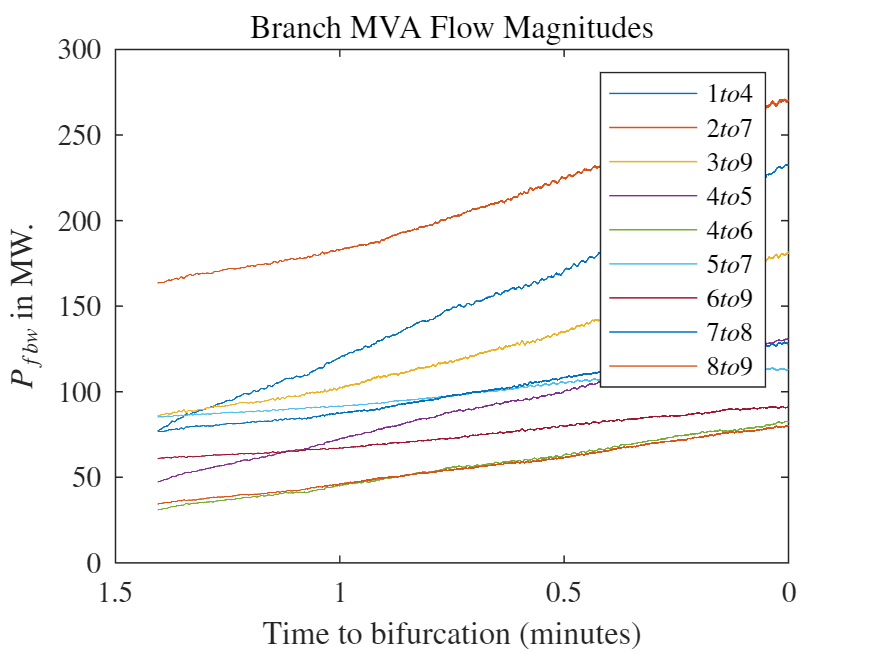

set(gcf, 'PaperSize', [24 12]); %set the paper size to what you want  
print(imagePdfName,'-dpdf', '-fillpage') % then print it

labelSmoothMVAflows = {'$Smooth(1 to 4)$', '$Smooth(2 to 7)$', ...
    '$Smooth(3 to 9)$', '$Smooth(4 to 5)$', '$Smooth(4 to 6)$', ...
    '$Smooth(5 to 7)$', '$Smooth(6 to 9)$', '$Smooth(7 to 8)$', '$Smooth(8 to 9)$'};
name_labelSmoothMVAflows = strcat(folder_name, 'labelSmoothMVAflows_'...
    , system_name, '.mat');
save(name_labelSmoothMVAflows, "labelSmoothMVAflows");

labelDeltaMVAflows = {'$d(1 to 4)$', '$d(2 to 7)$', ...
    '$d(3 to 9)$', '$d(4 to 5)$', '$d(4 to 6)$', ...
    '$d(5 to 7)$', '$d(6 to 9)$', '$d(7 to 8)$', '$d(8 to 9)$'};
name_labelDeltaMVAflows = strcat(folder_name, 'labelDeltaMVAflows_'...
    , system_name, '.mat');
save(name_labelDeltaMVAflows, "labelDeltaMVAflows");

labelARDeltaMVAflows = {'$a_1(d(1 to 4))$', '$a_1(d(2 to 7))$', ...
    '$a_1(d(3 to 9))$', '$a_1(d(4 to 5))$', '$a_1(d(4 to 6))$', ...
    '$a_1(d(5 to 7))$', '$a_1(d(6 to 9))$', '$a_1(d(7 to 8))$', '$a_1(d(8 to 9))$'};
name_labelARDeltaMVAflows = strcat(folder_name, 'labelARDeltaMVAflows_'...
    , system_name, '.mat');
save(name_labelARDeltaMVAflows, "labelARDeltaMVAflows");

labelVarDeltaMVAflows = {'$\sigma^2(d(1 to 4))$', '$\sigma^2(d(2 to 7))$', ...
    '$\sigma^2(d(3 to 9))$', '$\sigma^2(d(4 to 5))$', '$\sigma^2(d(4 to 6))$', ...
    '$\sigma^2(d(5 to 7))$', '$\sigma^2(d(6 to 9))$', '$\sigma^2(d(7 to 8))$', '$\sigma^2(d(8 to 9))$'};
name_labelVarDeltaMVAflows = strcat(folder_name, 'labelVarDeltaMVAflows_'...
    , system_name, '.mat');
save(name_labelVarDeltaMVAflows, "labelVarDeltaMVAflows");

if strcmp(system_name,'ieee9')
    leg1 = legend(labelMVAflows);   
elseif strcmp(system_name,'ieee39')
    leg1 = legend('MVA flows missing for ieee39.');
else
    legend;
end

#### Plot Branch Currents.

figure('Name', 'Branch Current Flows')
plot(xaxis1, ...
    currentsArr(indicesToPlot1,1:end));
set(gca,'xdir','reverse')
title('Branch Current Magnitudes');
xlabel('Time to bifurcation (minutes)');
ylabel('Currents in $A$.');

labelcurrents = {'$1 to 4$', '$2 to 7$', '$3 to 9$', ...
    '$4 to 5$', '$4 to 6$', '$5 to 7$', ...
    '$6 to 9$', '$7 to 8$', '$8 to 9$'};
name_labelcurrents = strcat(folder_name, 'labelcurrents_'...
    , system_name, '.mat');
save(name_labelcurrents, "labelcurrents");

imagePdfName = strcat(pdf_location_name, system_name,...
    'branchCurrents_T_',windowInSec)

imagePdfName = "pdf/ieee9branchCurrents_T_10_sec"

set(gcf, 'PaperSize', [24 12]); %set the paper size to what you want  
print(imagePdfName,'-dpdf', '-fillpage') % then print it

labelSmoothcurrents = {'$Smooth(1 to 4)$', '$Smooth(2 to 7)$', ...
    '$Smooth(3 to 9)$', '$Smooth(4 to 5)$', '$Smooth(4 to 6)$', ...
    '$Smooth(5 to 7)$', '$Smooth(6 to 9)$', '$Smooth(7 to 8)$', '$Smooth(8 to 9)$'};
name_labelSmoothcurrents = strcat(folder_name, 'labelSmoothcurrents_'...
    , system_name, '.mat');
save(name_labelSmoothcurrents, "labelSmoothcurrents");

labelDeltacurrents = {'$d(1 to 4)$', '$d(2 to 7)$', ...
    '$d(3 to 9)$', '$d(4 to 5)$', '$d(4 to 6)$', ...
    '$d(5 to 7)$', '$d(6 to 9)$', '$d(7 to 8)$', '$d(8 to 9)$'};
name_labelDeltacurrents = strcat(folder_name, 'labelDeltacurrents_'...
    , system_name, '.mat');
save(name_labelDeltacurrents, "labelDeltacurrents");

labelARDeltacurrents = {'$a_1(d(1 to 4))$', '$a_1(d(2 to 7))$', ...
    '$a_1(d(3 to 9))$', '$a_1(d(4 to 5))$', '$a_1(d(4 to 6))$', ...
    '$a_1(d(5 to 7))$', '$a_1(d(6 to 9))$', '$a_1(d(7 to 8))$', '$a_1(d(8 to 9))$'};
name_labelARDeltacurrents = strcat(folder_name, 'labelARDeltacurrents_'...
    , system_name, '.mat');
save(name_labelARDeltacurrents, "labelARDeltacurrents");

labelVarDeltacurrents = {'$\sigma^2(d(1 to 4))$', '$\sigma^2(d(2 to 7))$', ...
    '$\sigma^2(d(3 to 9))$', '$\sigma^2(d(4 to 5))$', '$\sigma^2(d(4 to 6))$', ...
    '$\sigma^2(d(5 to 7))$', '$\sigma^2(d(6 to 9))$', '$\sigma^2(d(7 to 8))$', '$\sigma^2(d(8 to 9))$'};
name_labelVarDeltacurrents = strcat(folder_name, 'labelVarDeltacurrents_'...
    , system_name, '.mat');
save(name_labelVarDeltacurrents, "labelVarDeltacurrents");

if strcmp(system_name,'ieee9')
    leg1 = legend(labelcurrents);   
elseif strcmp(system_name,'ieee39')
    leg1 = legend('Legend Missing for ieee39');
else
    legend;
end

#### Plot Bus Voltages.

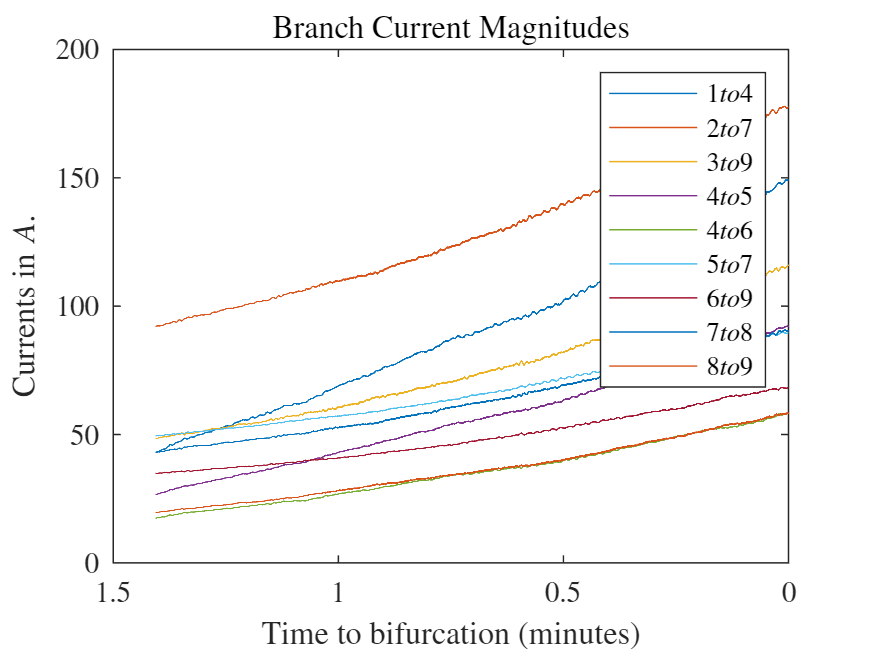

indicesToPlot2 = 1:downsampling_ratio:bifurcationIdx-W;
xaxis2 = (bifurcationIdx - indicesToPlot2)*sampling_rate/(60);

subplot(1,1,1)



figure('Name', 'Bus Voltages')

plot(xaxis1, volts(indicesToPlot1,1:end));
% yyaxis left
set(gca,'xdir','reverse')
labelVoltages = {'$V_1$', '$V_2$', '$V_3$', '$V_4$',...
    '$V_5$', '$V_6$', '$V_7$', '$V_8$', '$V_9$'};
name_labelVoltages = strcat(folder_name, 'labelVoltages_'...
    , system_name, '.mat');
save(name_labelVoltages, "labelVoltages");

labelSmoothVoltages = {'$Smooth(V_1)$', '$Smooth(V_2)$', '$Smooth(V_3)$', '$Smooth(V_4)$',...
    '$Smooth(V_5)$', '$Smooth(V_6)$', '$Smooth(V_7)$', '$Smooth(V_8)$', '$Smooth(V_9)$'};
name_labelSmoothVoltages = strcat(folder_name, 'labelSmoothVoltages_'...
    , system_name, '.mat');
save(name_labelSmoothVoltages, "labelSmoothVoltages");

labelDeltaVoltages = {'$d(V_1)$', '$d(V_2)$', '$d(V_3)$', '$d(V_4)$',...
    '$d(V_5)$', '$d(V_6)$', '$d(V_7)$', '$d(V_8)$', '$d(V_9)$'};
name_labelDeltaVoltages = strcat(folder_name, 'labelDeltaVoltages_'...
    , system_name, '.mat');
save(name_labelDeltaVoltages, "labelDeltaVoltages");

labelARDeltaVoltages = {'$a_1(d(V_1))$', '$a_1(d(V_2))$', '$a_1(d(V_3))$', '$a_1(d(V_4))$',...
    '$a_1(d(V_5))$', '$a_1(d(V_6))$', '$a_1(d(V_7))$', '$a_1(d(V_8))$', '$a_1(d(V_9))$'};
name_labelARDeltaVoltages = strcat(folder_name, 'labelARDeltaVoltages_'...
    , system_name, '.mat');
save(name_labelARDeltaVoltages, "labelARDeltaVoltages");

labelTauAR1Voltages = {'$\tau_{a_1(d(V_1))}$', '$\tau_{a_1(d(V_2))}$', ...
    '$\tau_{a_1(d(V_3))}$', '$\tau_{a_1(d(V_4))}$', ...
    '$\tau_{a_1(d(V_5))}$', '$\tau_{a_1(d(V_6))}$', ...
    '$\tau_{a_1(d(V_7))}$', '$\tau_{a_1(d(V_8))}$', ...
    '$\tau_{a_1(d(V_9))}$'};
name_labelTauAR1Voltages = strcat(folder_name, 'labelTauAR1Voltages_'...
    , system_name, '.mat');
save(name_labelTauAR1Voltages, "labelTauAR1Voltages");

labelpValAR1Voltages = {'$pVal_{a_1(d(V_1))}$', '$pVal_{a_1(d(V_2))}$', ...
    '$pVal_{a_1(d(V_3))}$', '$pVal_{a_1(d(V_4))}$', ...
    '$pVal_{a_1(d(V_5))}$', '$pVal_{a_1(d(V_6))}$', ...
    '$pVal_{a_1(d(V_7))}$', '$pVal_{a_1(d(V_8))}$', ...
    '$pVal_{a_1(d(V_9))}$'};
name_labelpValAR1Voltages = strcat(folder_name, 'labelpValAR1Voltages_'...
    , system_name, '.mat');
save(name_labelpValAR1Voltages, "labelpValAR1Voltages");

labelVarDeltaVoltages = {'$\sigma^2((d(V_1))$', '$\sigma^2(d(V_2))$', ...
    '$\sigma^2(d(V_3))$', '$\sigma^2(d(V_4))$', ...
    '$\sigma^2(d(V_5))$', '$\sigma^2(d(V_6))$', ...
    '$\sigma^2(d(V_7))$', '$\sigma^2(d(V_8))$', ...
    '$\sigma^2(d(V_9))$'};
name_labelVarDeltaVoltages = strcat(folder_name, 'labelVarDeltaVoltages_'...
    , system_name, '.mat');
save(name_labelVarDeltaVoltages, "labelVarDeltaVoltages");

labelTauVarVoltages = {'$\tau_{\sigma^2(d(V_1))}$', '$\tau_{\sigma^2(d(V_2))}$', ...
    '$\tau_{\sigma^2(d(V_3))}$', '$\tau_{\sigma^2(d(V_4))}$', ...
    '$\tau_{\sigma^2(d(V_5))}$', '$\tau_{\sigma^2(d(V_6))}$', ...
    '$\tau_{\sigma^2(d(V_7))}$', '$\tau_{\sigma^2(d(V_8))}$', ...
    '$\tau_{\sigma^2(d(V_9))}$'};
name_labelTauVarVoltages = strcat(folder_name, 'labelTauVarVoltages_'...
    , system_name, '.mat');
save(name_labelTauVarVoltages, "labelTauVarVoltages");

labelpValVarVoltages = {'$pVal_{\sigma^2(d(V_1))}$', '$pVal_{\sigma^2(d(V_2))}$', ...
    '$pVal_{\sigma^2(d(V_3))}$', '$pVal_{\sigma^2(d(V_4))}$', ...
    '$pVal_{\sigma^2(d(V_5))}$', '$pVal_{\sigma^2(d(V_6))}$', ...
    '$pVal_{\sigma^2(d(V_7))}$', '$pVal_{\sigma^2(d(V_8))}$', ...
    '$pVal_{\sigma^2(d(V_9))}$'};
name_labelpValVarVoltages = strcat(folder_name, 'labelpValVarVoltages_'...
    , system_name, '.mat');
save(name_labelpValVarVoltages, "labelpValVarVoltages");


legend(labelVoltages);
ylabel('Voltages in pu');
set(gca,'xdir','reverse')


xlabel('Time to bifurcation (minutes)');


title('Bus Voltage(s) vs', ...
    'a slow and constant increment in loads');

imagePdfName = strcat(pdf_location_name, system_name, '_', string(run_number), ...
    '_busVoltages_T_',windowInSec)

imagePdfName = "pdf/ieee9_1_busVoltages_T_10_sec"

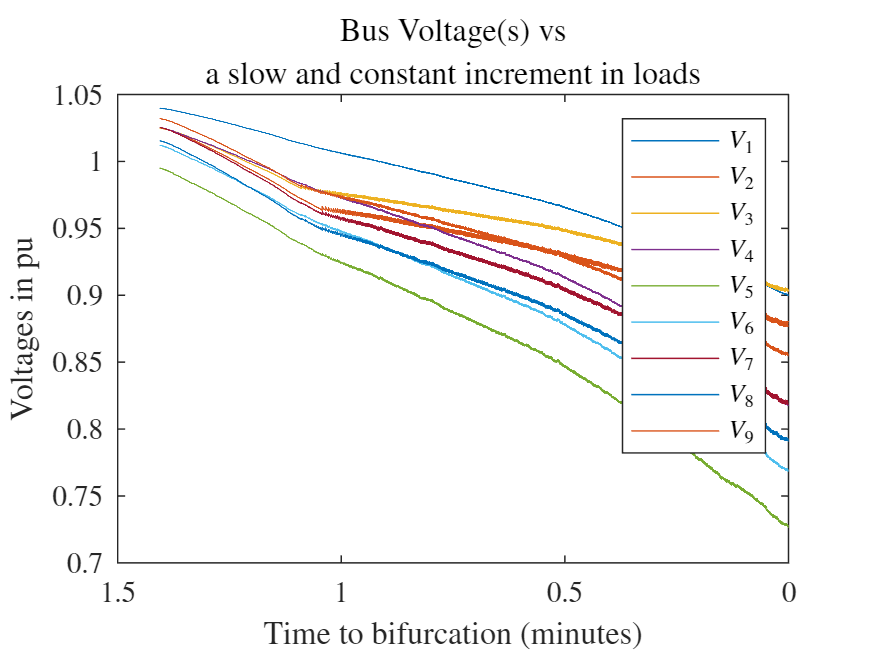

set(gcf, 'PaperSize', [24 12]); %set the paper size to what you want  
print(imagePdfName,'-dpdf', '-fillpage') % then print it


toc

Elapsed time is 13.134798 seconds.
